Starting by importing the image into matlabs

img = imread("Clocktower.jpg")

img = 1280×960×3 uint8 array
img(:,:,1) =

   218   218   218   218   218   218   218   218   218   218   218   218   218   218   218   217   217   216   216   216   216   216   216   216   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   210   210   210   210   210   210   210   210   212   212   211   211   211   211   209   209   208   208   206   206   206   206   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   204   204   204   204   204   204   204   

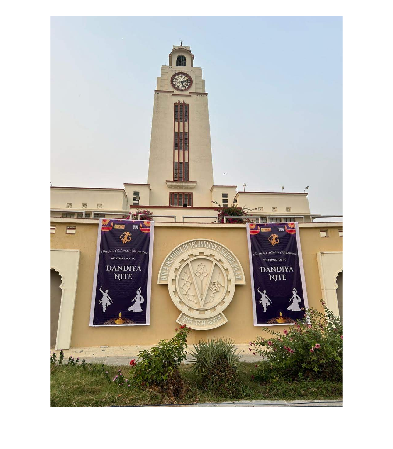

imshow(img)

blockSize = 16 %defining the size of our convolution matrix

blockSize = 16

Now we'll split up our image into the R, G and B values

imgBinned = zeros(size(img,1)/blockSize, size(img,2)/blockSize, size(img,3), "uint8")

imgBinned = 80×60×3 uint8 array
imgBinned(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

Now let's start iterating through the original img matrix

for i=1:blockSize:size(img,1)
    for j=1:blockSize:size(img,2)
        for k=1:1:size(img,3)
            tempSubMatrix = img(i:i+blockSize-1, j:j+blockSize-1, k); %BIG NOTE: don't remove the semicolon otherwise the program takes forever to compile because it prints EVERY matrix
            imgBinned(i,j,k) = ceil(mean(mean(tempSubMatrix)));
        end
    end
end

Fixing the fact that the loop is messed up somewhere and I'm too lazy to actually fix it, so we just remove every other line 🤡

imgBinned

imgBinned = 1265×945×3 uint8 array
imgBinned(:,:,1) =

   218     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   216     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   215     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   212     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   212     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   212     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   211     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   209     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   206     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   205     0     0     0     0     0     0     0     0     0     0     0     0   

imgBinned = imgBinned(1:blockSize:end,1:blockSize:end,:) %I'm proud of myself for actually figuring this out lmao 😎

imgBinned = 80×60×3 uint8 array
imgBinned(:,:,1) =

   218   216   215   212   212   212   211   209   206   205   204   204   204   204   203   202   201   201   201   201   201   199   199   199   200   198   198   198   197   197   197   197   195   194   194   194   194   194   193   193   193   193   194   193   192   191   191   191   191   191   192   191   192   192   192   191   191   191   191   192
   218   218   216   213   213   212   211   210   206   206   204   204   204   204   204   202   202   201   201   201   201   201   200   199   197   199   198   198   198   197   198   197   195   194   194   194   194   194   194   193   193   193   193   193   193   192   192   191   191   192   192   192   193   193   193   193   192   192   191   191
   219   218   217   216   214   213   212   208   207   206   205   204   204   204   204   203   203   202   201   201   201   201   201   201   200   200   199   196   199   198   197   195   194   194   194   194   194   1

imgBinned

imgBinned = 80×60×3 uint8 array
imgBinned(:,:,1) =

   218   216   215   212   212   212   211   209   206   205   204   204   204   204   203   202   201   201   201   201   201   199   199   199   200   198   198   198   197   197   197   197   195   194   194   194   194   194   193   193   193   193   194   193   192   191   191   191   191   191   192   191   192   192   192   191   191   191   191   192
   218   218   216   213   213   212   211   210   206   206   204   204   204   204   204   202   202   201   201   201   201   201   200   199   197   199   198   198   198   197   198   197   195   194   194   194   194   194   194   193   193   193   193   193   193   192   192   191   191   192   192   192   193   193   193   193   192   192   191   191
   219   218   217   216   214   213   212   208   207   206   205   204   204   204   204   203   203   202   201   201   201   201   201   201   200   200   199   196   199   198   197   195   194   194   194   194   194   1

Showing the actual image and comparing

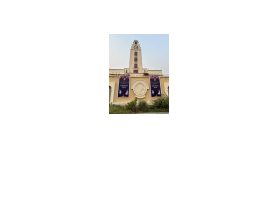

imshow(imgBinned)

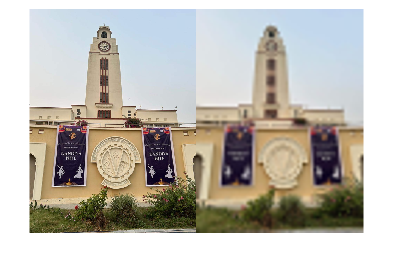

montage({img, imgBinned}, 'Size', [1 2])

And because I'm bored here's how it looks in all 3 colors, both binned and not binned

imgRed = imgBinned